## Toy example on how to visualize fastcore model output using the new pipeline

This example is meant to show the different types of visualizations you can do to further inspect your models build with fastcore. 

Read in object with the stored singleModelAnalysis:

working_path = "/Users/leonie.thomas/Documents/fastcore_workflow_with_vanille";
load(working_path + filesep + "context_specific_models" + filesep + "20260119_1042" + filesep + "project_23012026_1453_28012026_1508_obj_vanille_sampling_20260306_sampling.mat")

Execute the comparison model function: 

% choose which models to compare
modelList = ["WT","KO","PLV"];
% choose which of the analysis stored in the object to compare 
% by default: the most recent one (name of the object is the date)
[project, analysisID] = chooseActiveAnalysisForComparison(project,modelList);

% choose the model which entails all the reactions and metabolites
referenceModel = "consistent_medium_constrained_model";
% choose which of the analysis you want to expecute
identifier = "_test";

[project,comparison_name] = modelsComparison(project,modelList, analysisID,...
                                            referenceModel,"modelStructureComparison",identifier);

modelsToTest = 1×4 string array
    "WT"    "KO"    "PLV"    "consistent_medium_constrained_model"


Transcripts will temporarily be removed to allow matching with the discretized data.
1258 of 1261 genes of the model matched
Transcripts will temporarily be removed to allow matching with the discretized data.
1253 of 1256 genes of the model matched
Transcripts will temporarily be removed to allow matching with the discretized data.
1274 of 1277 genes of the model matched
Transcripts will temporarily be removed to allow matching with the discretized data.
1264 of 1267 genes of the model matched


ans = 3×3 table
           count_reactions    count_metabolites    count_genes
           _______________    _________________    ___________

    KO        {[2421]}            {[1951]}          {[1261]}  
    PLV       {[2412]}            {[1939]}          {[1256]}  
    WT        {[2514]}            {[2024]}          {[1277]}  


plots = project.comparisons.(comparison_name).plots;

### Structural vs. Functional model comparison

Working with context-specific metabolic models, 2  of the main analysis routes are the structural vs. the functional model analysis. Since we construct models using fastcormics, the models have different reations in their models. 

Therefore before inspecting the behaviour of the models using FVA, FBA, and sampling we check how different the models are on a structural basis, and how many of those changes are based on the expression data we give as an input. This also is one QC measure of the models, since we ensure that the functional changes we see later in the functional analysis are based on the expression data we give as an input and are not due to other effects. 

#### Size of the context specific models:

- Inter and outersections of reactions between the models: 

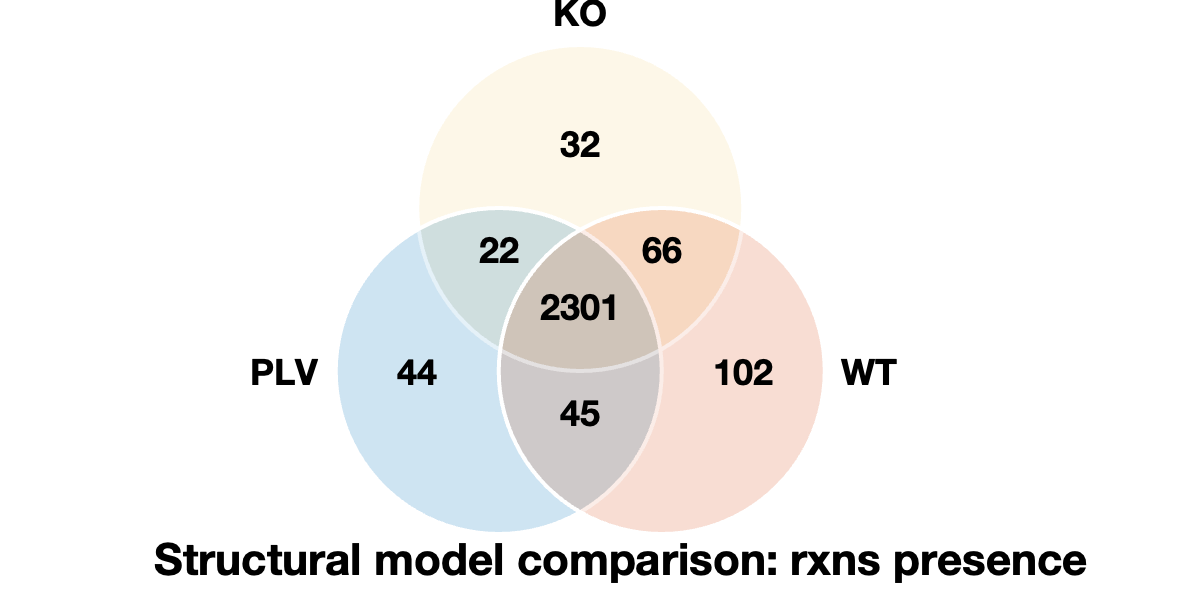

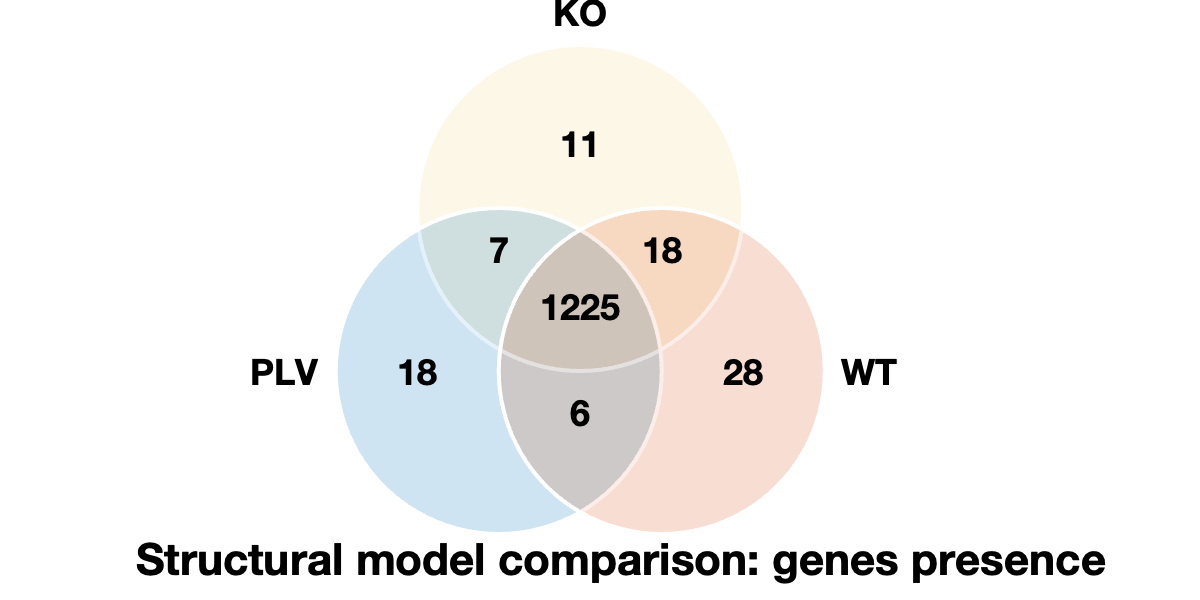

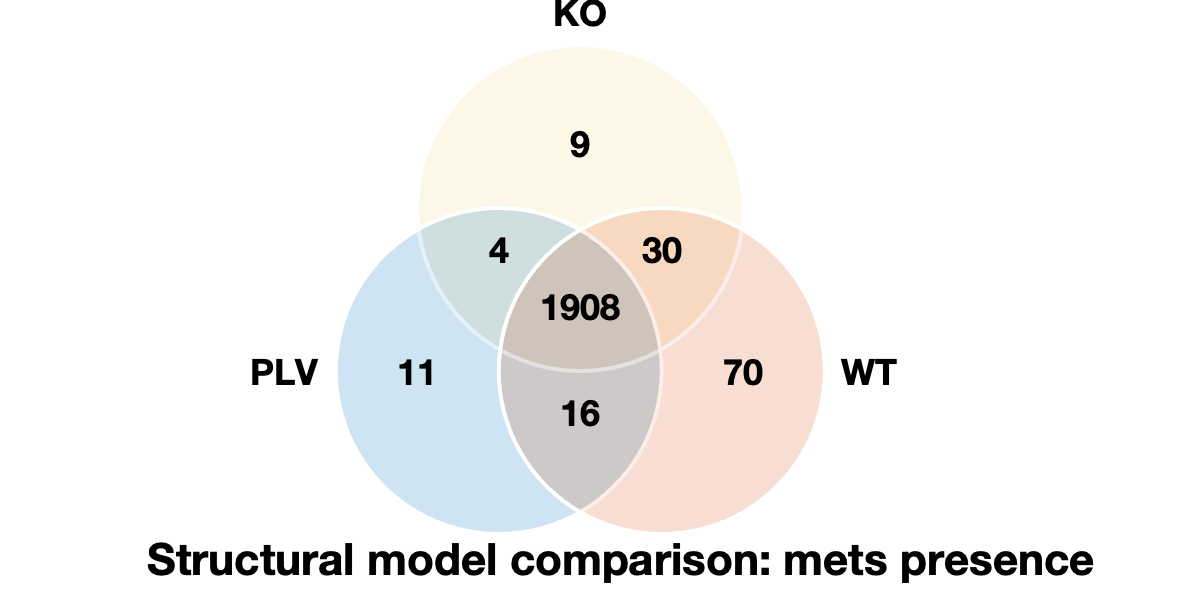

figure(copyobj(plots.intersections.rxns, groot));figure(copyobj(plots.intersections.genes, groot));figure(copyobj(plots.intersections.mets, groot));